# 最小均方误差准则(MMSE)/SLC自适应数字副瓣对消

最小均方误差准则(Minimum Mean Sequare Error,MMSE)指的是调整权值矢量使得输出信号与期望信号的均方误差值最小，适用于提前已知期望信号的方向信息或者接受信号中包含期望信号相关信息的情况。

假设d(n)是获取的参考信号，则输出信号与参考信号之间的误差可以表示为e(n) = d(n)-y(n),可以构建最小均方误差准则的最优化函数为:

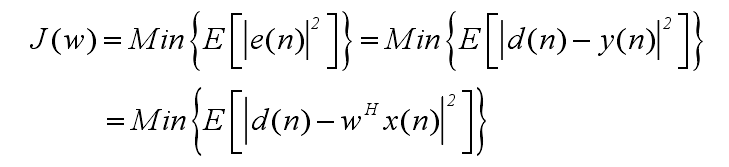

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 16;                                                                      %阵元个数
theta = [-20 10 25];                                                         %信号 干扰 干扰
M = numel(theta);                                                           %信源个数
snr = 10;                                                                   %信噪比
K = 1024;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号
X = A*S;                                                                    %对信号来向进行仿真
X1 = awgn(X,snr,'measured');

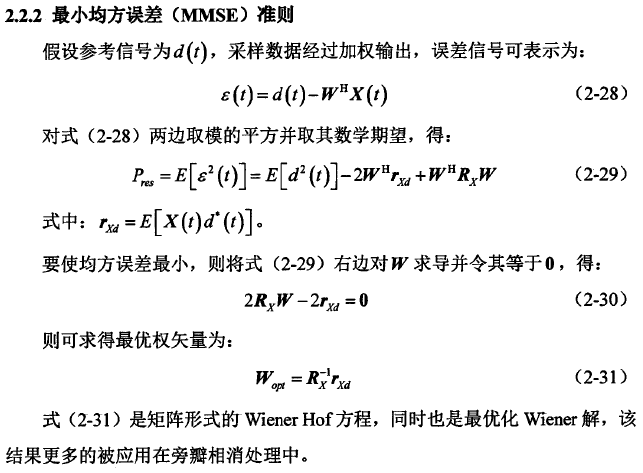

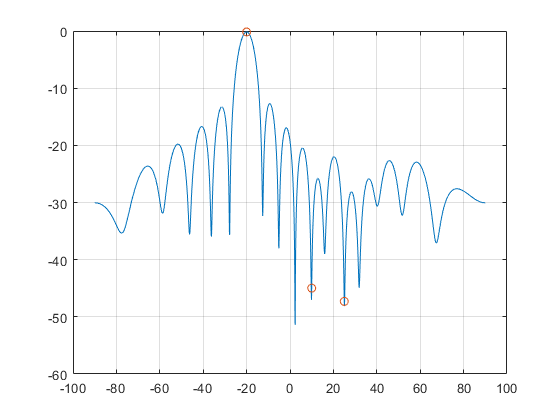

%--------------------------------------------------------------------------
%   构建模型
%   e = X - W*Y
%--------------------------------------------------------------------------
X = S(1,:);                                                                 %参考信号,已知信号的形态
Y = X1;                                                                     %接收信号矩阵

R_YX = Y*X';                                                                %互相关矩阵
R_YY = Y*Y';                                                                %自相关矩阵

w_opt = R_YY^-1*R_YX;                                                       %最优权矢量

%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
idx = 1;
for theta_d = -90:0.1:90
    A1 = exp(1j.*2*pi*d.'*sind(theta_d));
    output(idx) = w_opt'*A1;                                                %这里为啥出来了一个共轭？ 一脸问号
    idx = idx + 1;
end

%--------------------------------------------------------------------------
%   计算 信号 干扰角度
%--------------------------------------------------------------------------
for idx = 1:length(theta)
    index(idx) = find([-90:0.1:90]==theta(idx));
end

figure(1)
plot(-90:0.1:90,db(abs(output)));grid on;hold on
plot(theta,db(abs(output(index))),'o');
hold off